# Practica 9. Respuesta en frecuencia.

1. Utilice la función freqz() para graficar la respuesta en frecuencia del siguiente sistema:


$$\textrm{𝑦}\left(\textrm{𝑛}\right)-\frac{9}{10}\textrm{𝑦}\left(\textrm{𝑛}-1\right)+\frac{1}{3}\textrm{𝑦}\left(\textrm{𝑛}-2\right)=0\ldotp 11\left(\textrm{𝑥}\left(\textrm{𝑛}\right)+2\textrm{𝑥}\left(\textrm{𝑛}-1\right)+\textrm{𝑥}\left(\textrm{𝑛}-2\right)\right)$$


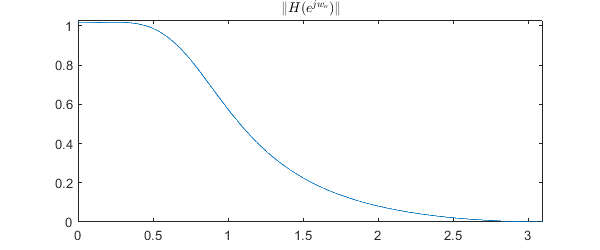

figure('Position',[500 400 600 250])
a = [1 -9/10 1/3];
b0 = 0.11;
b = .11*[1 2 1];
[h,w] = freqz(b,a);
plot(w,abs(h))
title('$\|H(e^{jw_{o}})\|$','Interpreter','latex')
xlim([0 3.1])
ylim([0 1.03])

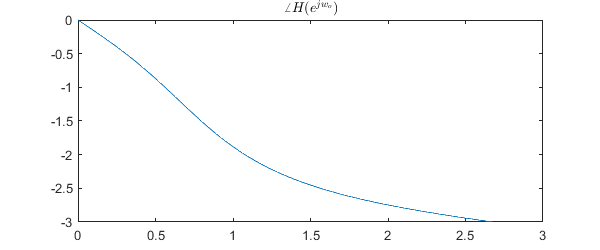

plot(w,angle(h))
title('$\angle H(e^{jw_{o}})$','Interpreter','latex')
xlim([0 3])
ylim([-3 0])

2. Utilice la función freqz() para graficar la respuesta en frecuencia del siguiente sistema:


$$\textrm{𝑦}\left(\textrm{𝑛}\right)-\frac{9}{10}\textrm{𝑦}\left(\textrm{𝑛}-1\right)+\frac{1}{3}\textrm{𝑦}\left(\textrm{𝑛}-2\right)=0\ldotp 67\left(\textrm{𝑥}\left(\textrm{𝑛}\right)-2\textrm{𝑥}\left(\textrm{𝑛}-1\right)+\textrm{𝑥}\left(\textrm{𝑛}-2\right)\right)$$


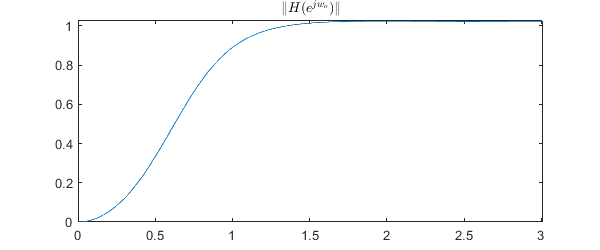

figure('Position',[500 400 600 250])
a = [1 -9/10 1/3];
b0 = 0.11;
b = .57*[1 -2 1];
[h,w] = freqz(b,a);
plot(w,abs(h))
title('$\|H(e^{jw_{o}})\|$','Interpreter','latex')
xlim([0 3.01])
ylim([0 1.03])

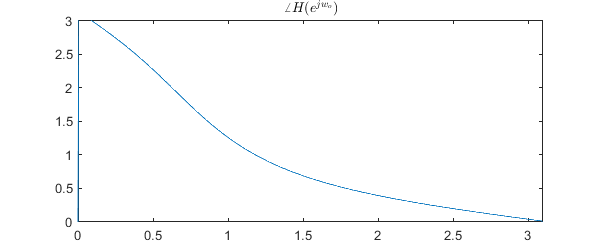

plot(w,angle(h))
title('$\angle H(e^{jw_{o}})$','Interpreter','latex')
xlim([0 3.1])
ylim([0 3.01])

3.Utilice la función freqz() para graficar la respuesta en frecuencia del siguiente sistema:


$$y\left(n\right)+\frac{1}{2}y\left(n-2\right)=0\ldotp 25\left(x\left(n\right)-x\left(n-2\right)\right)$$


Clasifique el sistema como pasa-bajas, pasa-altas, pasa-banda o rechaza-banda.

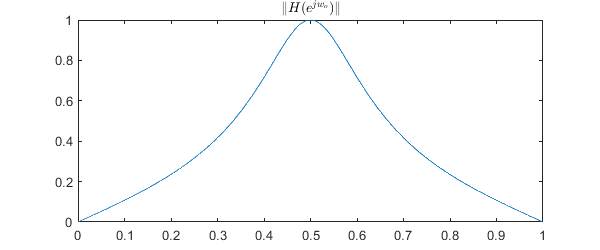

a = [1 0 1/2]; 
b = [0.25 0 -0.25]; 
[h,w] = freqz(b,a); 
plot(w/pi, abs(h))
title('$\|H(e^{jw_{o}})\|$','Interpreter','latex')

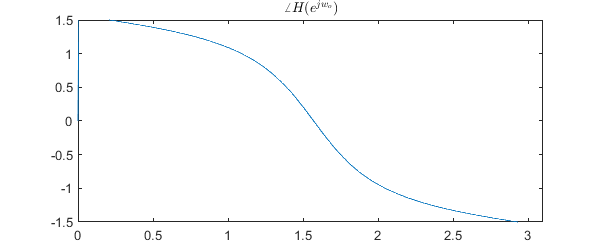

plot(w,angle(h))
title('$\angle H(e^{jw_{o}})$','Interpreter','latex')
xlim([0 3.1])
ylim([-1.5 1.5])

4. Utilice la función freqz() para graficar la respuesta en frecuencia del siguiente sistema:


$$y\left(n\right)+\frac{1}{2}y\left(n-2\right)=0\ldotp 75\left(x\left(n\right)+x\left(n-2\right)\right)$$


Clasifique el sistema como pasa-bajas, pasa-altas, pasa-banda o rechaza-banda.

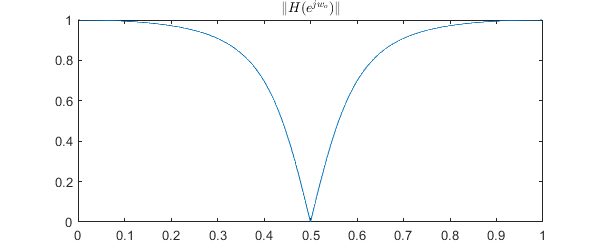

a = [1 0 1/2]; 
b = [0.75 0 0.75]; 
[h,w] = freqz(b,a); 
plot(w/pi, abs(h))
title('$\|H(e^{jw_{o}})\|$','Interpreter','latex')
xlim([0 1])
ylim([0 1])

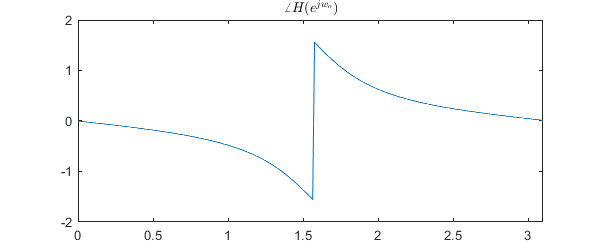

plot(w,angle(h))
title('$\angle H(e^{jw_{o}})$','Interpreter','latex')
xlim([0 3.1])
ylim([-2 2])

5.Utilice la  función freqz() para determinar  la amplitud  y  la  fase de la  señal de salida $y\left(n\right)$del sistema  con respuesta en  frecuencia $H\left(e^{\textrm{jw}} \right)=\frac{0\ldotp 3\;\left(1-e^{\;-\textrm{jw}} \right)}{1+\frac{4}{10}e^{\;-\textrm{jw}} }$ cuando  la  entrada  es la  señal  de tiempo discreto $x\left(n\right)=2\;\cos \;\left(\frac{2\;\pi \;n}{30}\right)$. Grafique las señales de entrada y de salida.

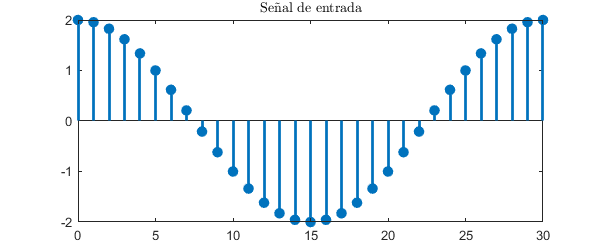

n = [0:30];
x = 2*cos(2*pi*n/30);
w = [0 (2*pi)/30];
stem(n,x,'filled','LineWidth',2)
title('Se\~{n}al de entrada','Interpreter','latex')

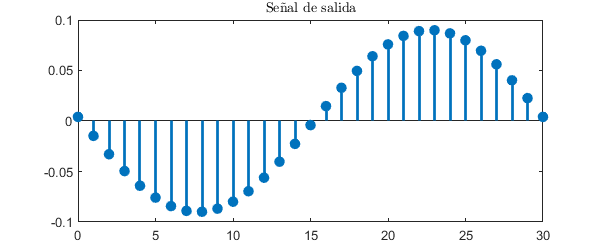

b = [.3  -.3]; 
a = [1 4/10]; 
h = freqz(b,a,w);   
y = 2*abs(h(2))*cos(2*pi*n/30+angle(h(2)));
stem(n,y,'filled','LineWidth',2)
title('Se\~{n}al de salida','Interpreter','latex')

6.Utilice la  función freqz() para determinar  la amplitud  y  la  fase de la  señal desalida $y\left(n\right)$del sistema  con respuesta en  frecuencia $H\left(e^{\textrm{jw}} \right)=\frac{1}{1-\frac{5}{6}e^{\;-\textrm{jw}} +\frac{1}{6}e^{\;-\;2\textrm{jw}} }$cuando  la  entrada  esla  señal  de tiempo discreto $x\left(n\right)=3\;\textrm{sen}\;\left(\frac{\pi \;n}{4}\right)$. Grafique las señales de entrada y de salida

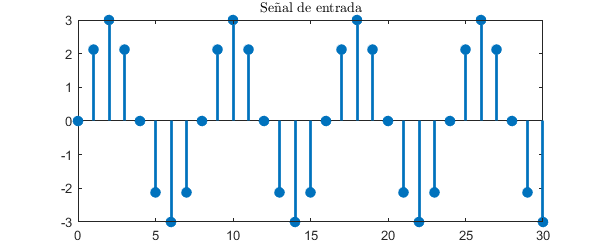

n = [0:30];
x = 3*sin(pi*n/4);
w = [0 pi/4];
stem(n,x,'filled','LineWidth',2)
title('Se\~{n}al de entrada','Interpreter','latex')

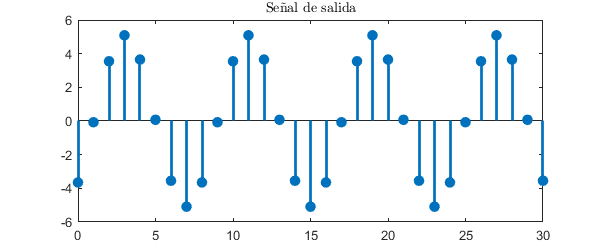

a = [1 -5/6 1/6];
b = [1];
h = freqz(b,a,w);   
y = 3*abs(h(2))*sin(pi*n/4+angle(h(2)));
stem(n,y,'filled','LineWidth',2)
title('Se\~{n}al de salida','Interpreter','latex')

Anexo

%Ejercicio 1

figure('Position',[500 400 600 250])

a = [1 -9/10 1/3];

b0 = 0.11;

b = .11*[1 2 1];

[h,w] = freqz(b,a);

plot(w,abs(h))

title('$\|H(e^{jw_{o}})\|$','Interpreter','latex')

xlim([0 3.1])

ylim([0 1.03])

plot(w,angle(h))

title('$\angle H(e^{jw_{o}})$','Interpreter','latex')

xlim([0 3])

ylim([-3 0])

%Ejercicio 2

figure('Position',[500 400 600 250])

a = [1 -9/10 1/3];

b0 = 0.11;

b = .57*[1 -2 1];

[h,w] = freqz(b,a);

plot(w,abs(h))

title('$\|H(e^{jw_{o}})\|$','Interpreter','latex')

xlim([0 3.01])

ylim([0 1.03])

plot(w,angle(h))

title('$\angle H(e^{jw_{o}})$','Interpreter','latex')

xlim([0 3.1])

ylim([0 3.01])

%Ejercicio 3

a = [1 0 1/2]; 

b = [0.25 0 -0.25]; 

[h,w] = freqz(b,a); 

plot(w/pi, abs(h))

title('$\|H(e^{jw_{o}})\|$','Interpreter','latex')

plot(w,angle(h))

title('$\angle H(e^{jw_{o}})$','Interpreter','latex')

xlim([0 3.1])

ylim([-1.5 1.5])

%Ejercicio 4

a = [1 0 1/2]; 

b = [0.75 0 0.75]; 

[h,w] = freqz(b,a); 

plot(w/pi, abs(h))

title('$\|H(e^{jw_{o}})\|$','Interpreter','latex')

xlim([0 1])

ylim([0 1])

plot(w,angle(h))

title('$\angle H(e^{jw_{o}})$','Interpreter','latex')

xlim([0 3.1])

ylim([-2 2])

%Ejercicio 5

n = [0:30];

x = 2*cos(2*pi*n/30);

w = [0 (2*pi)/30];

stem(n,x,'filled','LineWidth',2)

title('Se\~{n}al de entrada','Interpreter','latex')

b = [.3  -.3]; 

a = [1 4/10]; 

h = freqz(b,a,w);   

y = 2*abs(h(2))*cos(2*pi*n/30+angle(h(2)));

stem(n,y,'filled','LineWidth',2)

title('Se\~{n}al de salida','Interpreter','latex')

%Ejercicio 6

n = [0:30];

x = 3*sin(pi*n/4);

w = [0 pi/4];

stem(n,x,'filled','LineWidth',2)

title('Se\~{n}al de entrada','Interpreter','latex')

a = [1 -5/6 1/6];

b = [1];

h = freqz(b,a,w);   

y = 3*abs(h(2))*sin(pi*n/4+angle(h(2)));

stem(n,y,'filled','LineWidth',2)

title('Se\~{n}al de salida','Interpreter','latex')